## Lecture 2

### Ex 1.

#### 1)

Transfer function: $\frac{\textrm{Kp}}{s^2 +s+\textrm{Kp}}$

For at finde overshoot så kan man aflæse grafen på slide 12.

$\zeta \approx 0\ldotp 45$ for $20%$ overshoot


$$2\zeta \omega_n =1$$



$$\omega_n^2 =\textrm{Kp}\Leftrightarrow \omega_n =\sqrt{\textrm{Kp}}$$



$$2\cdot 0\ldotp 45\cdot \sqrt{\textrm{Kp}}=1\Leftrightarrow \textrm{Kp}=1\ldotp 23$$


syms Kp
vpa(solve(2*0.45*sqrt(Kp)==1,Kp));

#### 2)

Rise time and settle time:


$$\omega_n =\sqrt{\textrm{Kp}}=\sqrt{1\ldotp 23}=1\ldotp 109$$



$$T_r \approx \frac{1\ldotp 8}{\omega_n }=\frac{1\ldotp 8}{1\ldotp 109}=1\ldotp 6\;\textrm{sekunder}$$


$T_s \left(x\right)=\frac{-\ln \left(x\right)}{\omega_n \zeta }=\frac{-\ln \left(0\ldotp 02\right)}{1\ldotp 109\cdot 0\ldotp 45}=7\ldotp 8\;\textrm{sekunder}$ hvor x er settle time i procent.

-log(0.02)/(1.109*0.45);

#### 3)

System type 1 se systemet skal betragtet som Open Loop!


$$K_v =\lim_{s\to 0} \;s\cdot G\left(s\right)$$
 
$$=\lim_{s\to 0} \;s\cdot \frac{K}{s+1}\cdot \frac{1}{s}=K=1\ldotp 23$$



$$K_p =\lim_{s\to 0} \;G\left(s\right)=\lim_{s\to 0} \frac{K}{s+1}\cdot \frac{1}{s}=\infty$$



$$K_a =s^2 \cdot \lim_{s\to 0} \;G\left(s\right)=\lim_{s\to 0} \;s^2 \frac{K}{s+1}\cdot \frac{1}{s}=0$$


Deraf ved man systemet er af type 1 se slides side:

### Ex 2.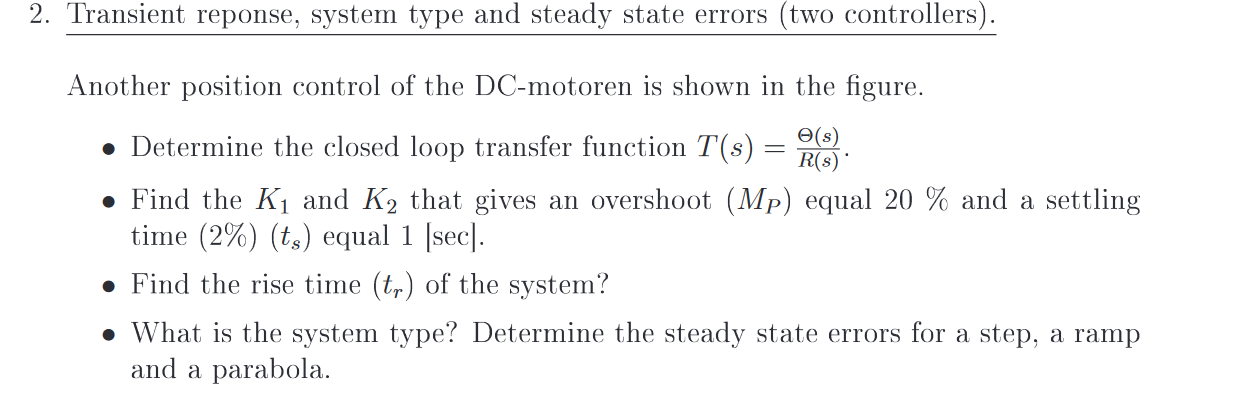

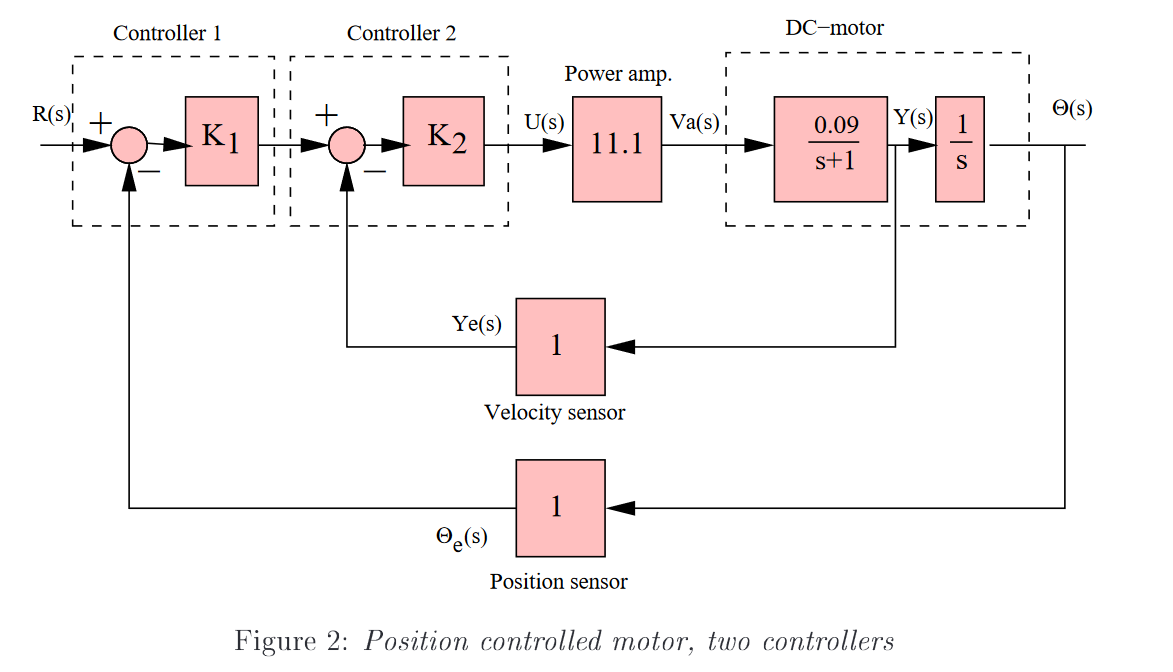

#### 1)

Transfer function:

Reducer det første med velocity sensor som close loop: $\frac{K_2 \frac{1}{s+1}}{1+K_2 \frac{1}{s+1}}$ reducér $\frac{\frac{K_2 }{s+1}}{\frac{s+1+K_2 }{s+1}}=\frac{K_2 s+K_2 }{s^2 +2s+K_2 s+K_2 +1}=\frac{K_2 \left(s+1\right)}{\left(s+1\right)\left(K_2 +s+1\right)}=\frac{K_2 }{\left(K_2 +s+1\right)}$ 

syms k1 k2 s
expr1 = (k2*11.1*(0.09/(s+1)))/(1+(k2*11.1*(0.09/(s+1))));
expr2 = (k1*expr1*(1/s))/(1+(k1*expr1*(1/s)));
collect(expr2,s); %fordi der rundes af så bliver der 1 i tæller og nævner i stedet for 999 og 1000 closed loop

$$ans = \frac{999\,k_{1}\,k_{2}}{1000\,s^{2}+\left(999\,k_{2}+1000\right)\,s+999\,k_{1}\,k_{2}}$$

#### 2)

Ved et overshoot på $\mathrm{Mp}=20%$ der er $\zeta \approx 0\ldotp 45$ses udfra fra en graf(slides), settle time % = 0.02% og $t_s =1$sekund


$$t_s \left(x\right)=\frac{-\ln \left(x\right)}{\zeta \omega_n }=\frac{-\ln \left(0\ldotp 02\right)}{0\ldotp 45\cdot \omega_n }=1\Leftrightarrow \omega_n =8\ldotp 7\;\mathrm{sekunder}$$


Herfra for at finde k1 og k2:


$$2\zeta \omega_n =K_2 +1\Leftrightarrow K_2 =2\zeta \omega_n -1=6\ldotp 8$$



$$\omega_n^2 =K_1 K_2 \Leftrightarrow K_1 =\frac{\omega^2 }{K_2 }=11\ldotp 1$$


#### 3)

$t_r \approx \frac{1\ldotp 8}{\omega_n }=\frac{1\ldotp 8}{8\ldotp 7}=0\ldotp 21$sekunder se slide 14

#### 4)

System type and system errors:

Open loop transfer function: $G\left(s\right)=\frac{K_1 K_2 }{K_2 +s+1}\cdot \frac{1}{s}$ her ses der er en pole i 0 deraf en type 1 alt dette findes på slide 23 og 24.


$$K_v =\lim_{s\to 0} \;\textrm{sG}\left(s\right)=s\cdot \frac{K_1 K_2 }{K_2 +s+1}\cdot \frac{1}{s}=\frac{K_1 K_2 }{K_2 +1}=9\ldotp 67$$


Error = $\frac{1}{K_v }=0\ldotp 1$

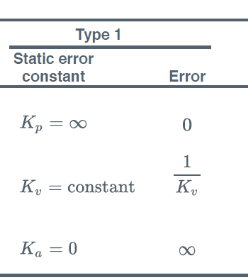    

clear all
close
syms s
k1 = 11.1;
k2 = 6.8;
x = limit((k1*k2)/(k2+s+1),s,0)

$$x = \frac{629}{65}$$

ess = vpa(1/x) %ramp grundet tabel og type

$$ess = 0.10333863275039745627980922098569$$

## Ex 3.

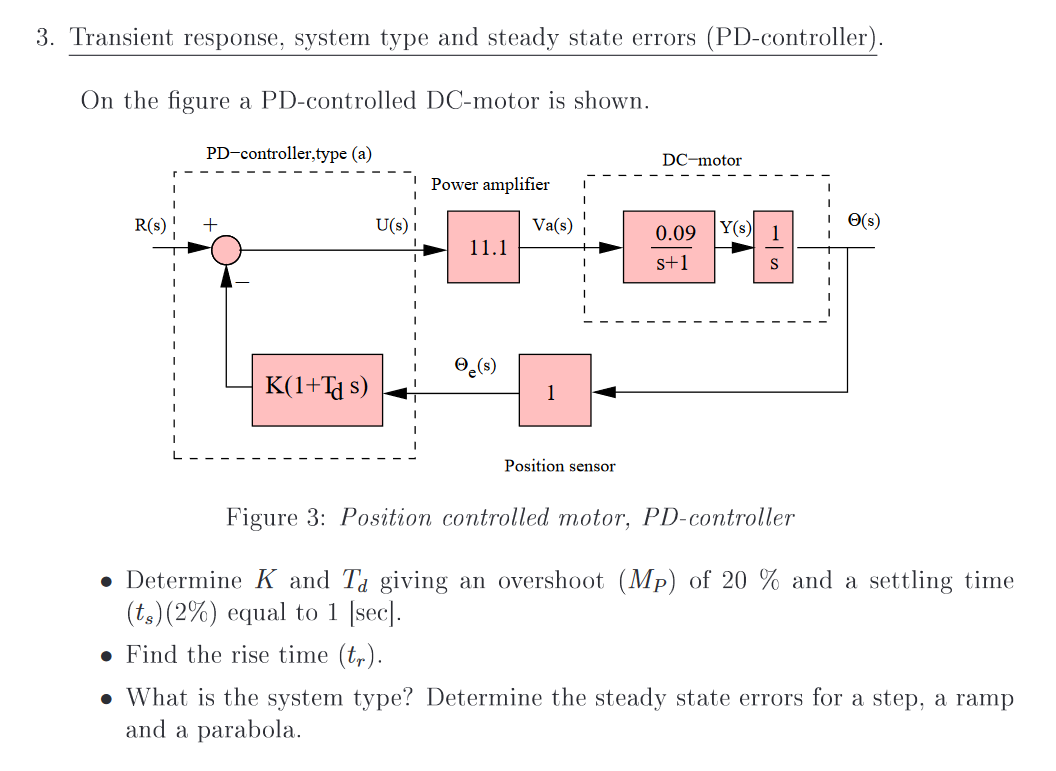

#### 1)

close all
clear
syms s K Td
expr1 = (1/(s+1))*1/s;
expr2 = K*(1+Td*s);
G = (expr1)/(1+(expr2*expr1)); %transfer function
collect(G,s)

$$ans = \frac{1}{s^{2}+\left(K\,\mathrm{Td}+1\right)\,s+K}$$

For at finde overshoot så kan man aflæse grafen på slide 12.

$\zeta \approx 0\ldotp 45$ for $20%$ overshoot


$$t_s \left(x\right)=\frac{-\ln \left(x\right)}{\zeta \omega_n }=\frac{-\ln \left(0\ldotp 02\right)}{0\ldotp 45\cdot \omega_n }=1\Leftrightarrow \omega_n =8\ldotp 7\;\textrm{sekunder}$$



$$\omega_n^2 =K=8\ldotp 7^2 =75\ldotp 7$$


$2\zeta \omega_n =T_d \cdot K+1\Leftrightarrow T_d =\frac{2\zeta \omega_n -1}{K}=0\ldotp 09\;$sekunder    

#### 2)


$$t_r \approx \frac{1\ldotp 8}{\omega_n }=\frac{\left(1\ldotp 8\right)}{\sqrt{\;75\ldotp 7}}=0\ldotp 2\;\textrm{sekunder}$$


#### 3)


$$\frac{1}{s^2 +{\left(\textrm{Td}\,K+1\right)}\,s+K}$$


Ingen unit feedback system derfor brug formel:

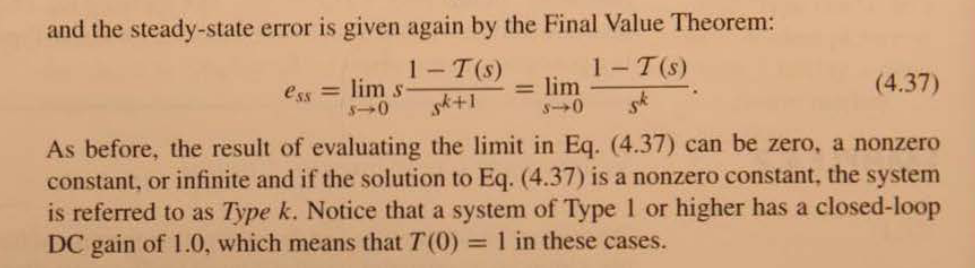


$$e_{\textrm{ss}} =\lim_{s\to 0} s\frac{1-T\left(s\right)}{s^{k+1} }=\lim_{s\to 0} \frac{1-T\left(s\right)}{s^k }$$


Closed loop transfer function: $T\left(s\right)=\frac{1}{s^2 +\left({\textrm{KT}}_d +1\right)s+K}$

$\underset{s\to 0}{e_{\textrm{ss}} =\lim } \frac{1-\frac{1}{s^2 +\left({\textrm{KT}}_d +1\right)s+K}}{s^k }$=$\lim_{s\to 0} \;\frac{\frac{s^2 +\left({\textrm{KT}}_d +1\right)s+K-1}{s^2 +\left({\textrm{KT}}_d +1\right)s+K}}{s^k }=\lim_{s\to 0} \;\frac{1}{s^k }\frac{K-1}{K}$når s er gået imod 0

Det er non zero når k = 0 derfor er systemet type k eller type 0

The steady state error for step: $e_{\textrm{ss}} =\lim_{s\to 0} \;s\left(1-T\left(s\right)\right)R\left(s\right)=\lim_{s\to 0} \left(1-T\left(s\right)\right)=\lim_{s\to 0} \left(\frac{s^2 +\left({\textrm{KT}}_d +1\right)s+K-1}{s^2 +\left({\textrm{KT}}_d +1\right)s+K}\right)=\frac{K-1}{K}=0\ldotp 9868$


$$y_{\textrm{ss}} =1-0\ldotp 9868=0\ldotp 0132$$


## Ex. 4

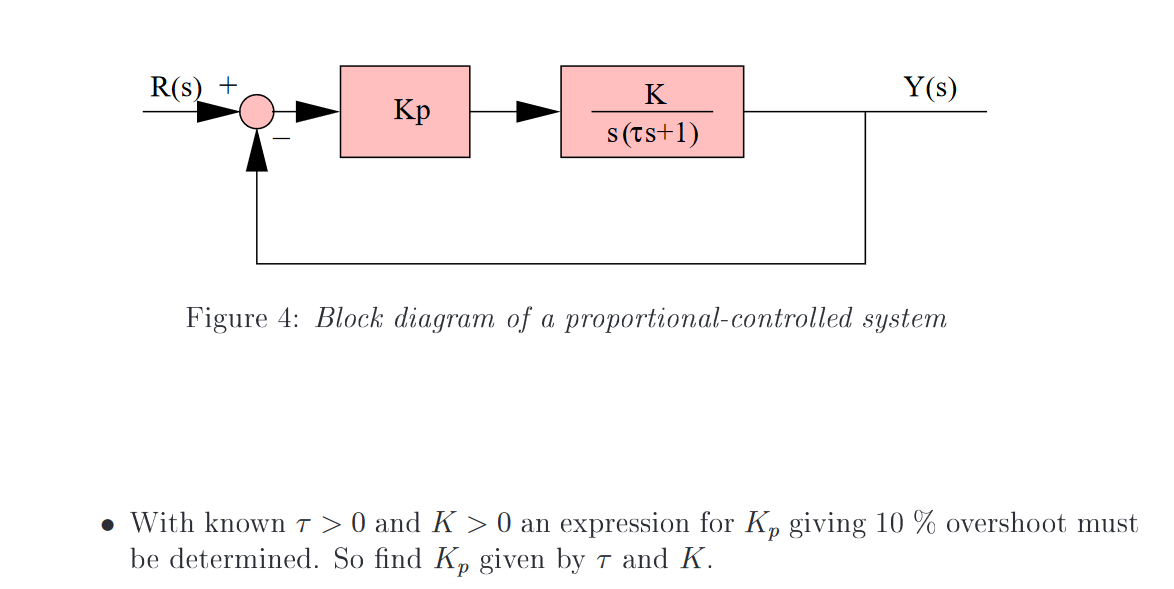

Close loop transfer function:


$$T\left(s\right)=\frac{\textrm{Kp}\cdot \frac{K}{s\left(\tau \;s+1\right)}}{1+\textrm{Kp}\cdot \frac{K}{s\left(\tau \;s+1\right)}}=\frac{\textrm{Kp}\cdot \;K}{s^2 \tau +s+\textrm{Kp}\cdot \;K}=\frac{\textrm{Kp}\cdot \;K}{\tau \;}\cdot \frac{1}{s^2 +\frac{s}{\tau }+\frac{\textrm{KpK}}{\tau }}$$



$$2\zeta \omega_n =\frac{1}{\tau }\;\textrm{og}\;\omega_n^2 =\frac{\textrm{KpK}}{\tau }$$



$$2\zeta \omega_n =\frac{1}{\tau }=2\zeta \sqrt{\frac{\textrm{KpK}}{\tau }}\Rightarrow \frac{1}{4\zeta^2 \tau }=K_p K\Rightarrow K_p =\frac{1}{4\zeta^2 \tau K}$$


sæt det her ind: Over shoot $10%\approx 6\ldotp 5\;\textrm{for}\;\;\zeta \;v\ae \textrm{rdi}$